% Read image
clc
clear

N = 16;

for i = 1:N
    if (i < 10)
        number = '0' + string(i);
    else
        number = string(i);
    end
    
    name = './DB1/db1_' + number + '.jpg';
    
    RGB = imread(name);
    
    croppedImage = faceDetection(RGB);
    
    grayImage = im2gray(croppedImage);
    
    image_vector(:,i) = grayImage(:);
     
end

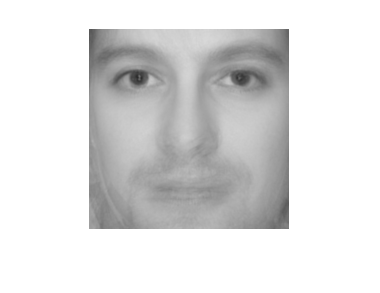

% 3. Mean-face
meanFace = sum(image_vector,2)/N;
meanFaceImage = reshape(meanFace, 200, 200)/255;
imshow(meanFaceImage);


% 4. Subtract mean
A = im2double(image_vector)-meanFace;

% 5. Covariance 
% C = AA';
% C1 = A'*A;

function croppedImage = faceDetection(RGB)
    % White balance
    rgbImageWhite = cWhitePatch(RGB);
    
    % Face mask
    mask = faceMask(rgbImageWhite);
    % disp('Face mask'), imshow(mask);
    
    % Eye map
    map = eyeMap(rgbImageWhite);
    % disp('Eye map'), imshow(eyeMap);
    
    % Combine
    res = map & mask;
    % disp('Eye map + face mask'), imshow(res);
    
    % Cleaning
    res = cleaning(res);
    
    % Get eye coordinates
    [lab,num]=bwlabel(res);
    stats = regionprops(lab);
    eye1 = getfield(stats,{1},'Centroid');
    y1 = eye1(1);
    x1 = eye1(2);
    eye2 = getfield(stats,{2},'Centroid');
    y2 = eye2(1);
    x2 = eye2(2);
    
    % Rotate the images based on the eyes
    rotatedImage = rotate_image(RGB,y1,x1,y2,x2);
    % disp('Rotated image'), imshow(rotatedImage);
    
    % Get new eye coordinates
    map = rotate_image(res,y1,x1,y2,x2);
    [lab,num]=bwlabel(map);
    stats2 = regionprops(lab);
    eye1 = getfield(stats2,{1},'Centroid');
    eye2 = getfield(stats2,{2},'Centroid');
    x1 = eye1(1);
    y1 = eye1(2);
    x2 = eye2(1);
    y2 = eye2(2);
    
    % Crop the image square for eigenfaces
    croppedImage = crop(rotatedImage, x1, y1, x2, y2);
end